# DMDc for ATMD system

## ATMD system

$x = [x_1 \,\, x_2 \,\, x_3 \,\, x_4]^T$ where

$x_1 = x_f$, $x_2=\dot{x}_f$, $x_3 = x_T$ and $x_4 = \dot{x}_T$

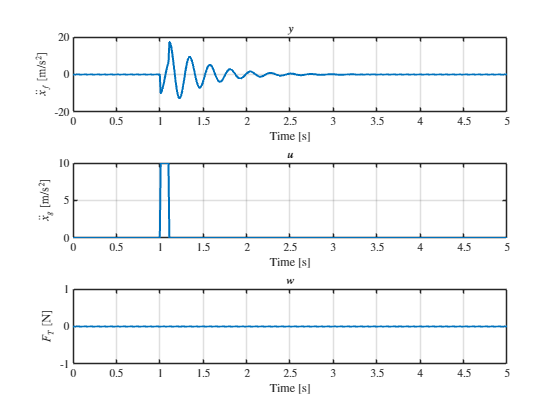

k_f = 500;
c_f = 3;
m_f = 0.68;
m_c = 0.39;
k_c = 0;
c_c = 0.5;
dt = 0.01;
t_f = 5;


% State-Space Matrices
A = [ 0                                        1     0                   0;
     -k_f/m_f                           -c_f/m_f     0             c_c/m_f;
      0                                        0     0                   1;
      k_f/m_f                            c_f/m_f     0     -c_c/m_c-c_c/m_f];

B = [ 0    0;
     -1   0;
      0    0;
      0   1/m_c];

C = [-k_f/m_f -c_f/m_f  0  c_c/m_f];

D = [-1   0];



% A = [          0          1                    0                   0;
%         -k_n/m_n   -c_n/m_n              k_T/m_n             c_T/m_n;
%                0          0                    0                   1;
%          k_n/m_n    c_n/m_n   -(k_T/m_T+k_T/m_n)  -(c_T/m_T+c_T/m_n)];

% A = [          0          1                    0                   0;
%         -k_n/m_n   -c_n/m_n                    0             c_T/m_n;
%                0          0                    0                   1;
%                0    c_T/m_T             -k_T/m_T            -c_T/m_T];
% 
% B = [   0    0;
%         0   -1;
%         0    0;  
%    1/m_T    0];
% 
% C = [-k_n/m_n   -c_n/m_n    k_T/m_n     c_T/m_n];

% C = [-k_n/m_n   -c_n/m_n    0     c_T/m_n];

% D = [0  -1];

SYS = ss(A,B,C,D);

t = 0:dt:t_f;
ddx_g = 10*(t>1)-10*(t>1.1);
% sine: 1*sin(10*t);
% unit = 10*(t>1)
F_T = zeros(1,length(t));

u = [ddx_g;
    F_T];

[Y,~,X,~] = lsim(SYS,u,t);

%%%%%%%%%%%%%%

figure;
subplot(3,1,1)
plot(t,Y,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_f$ [m/s$^2$]','Interpreter','latex')
title('$y$','Interpreter','latex')
grid on

subplot(3,1,2)
plot(t,ddx_g,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\ddot{x}_g$ [m/s$^2$]','Interpreter','latex')
title('$u$','Interpreter','latex')
grid on

subplot(3,1,3)
plot(t,F_T,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$F_T$ [N]','Interpreter','latex')
title('$w$','Interpreter','latex')
grid on

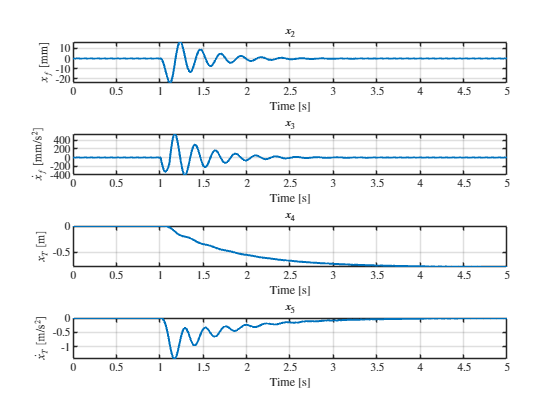


%%%%%%%%%%%%%%
figure;
subplot(4,1,1)
plot(t,X(:,1)*1000,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_f$ [mm]','Interpreter','latex')
title('$x_2$','Interpreter','latex')
grid on

subplot(4,1,2)
plot(t,X(:,2)*1000,'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_f$ [mm/s$^2$]','Interpreter','latex')
title('$x_3$','Interpreter','latex')
grid on

subplot(4,1,3)
plot(t,X(:,3),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_T$ [m]','Interpreter','latex')
title('$x_4$','Interpreter','latex')
grid on

subplot(4,1,4)
plot(t,X(:,4),'LineWidth',1.5)
set(gca,'TickLabelInterpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_T$ [m/s$^2$]','Interpreter','latex')
title('$x_5$','Interpreter','latex')
grid on